Alcune matrici particolari + autovalori, autovettori + spettro e raggio spettrale di matrici + come risolvere un sistema lineare + funzioni di plot (?).

Matrici particolari

A = rand(5)

A =     0.6761    0.2548    0.7805    0.9160    0.7702
    0.2891    0.2240    0.6753    0.0012    0.3225
    0.6718    0.6678    0.0067    0.4624    0.7847
    0.6951    0.8444    0.6022    0.4243    0.4714
    0.0680    0.3445    0.3868    0.4609    0.0358


Se vogliamo una matrice triangolare, possiamo usare:

triu (A) -> triangle upper

tril (A) -> triangle lower

U = triu(A)

U =     0.6761    0.2548    0.7805    0.9160    0.7702
         0    0.2240    0.6753    0.0012    0.3225
         0         0    0.0067    0.4624    0.7847
         0         0         0    0.4243    0.4714
         0         0         0         0    0.0358


L = tril(A)

L =     0.6761         0         0         0         0
    0.2891    0.2240         0         0         0
    0.6718    0.6678    0.0067         0         0
    0.6951    0.8444    0.6022    0.4243         0
    0.0680    0.3445    0.3868    0.4609    0.0358


A volte potremmo voler estrarre la matrice triangolare ma con anche la diagonale uguale a 0:

%0 0 0 0 0
%1 0 0 0 0
%1 2 0 0 0
%1 2 3 0 0
%1 2 3 4 0

Posso estrarre la diagonale usando la funzione diag(A)

D = diag(A) % Ritorna il vettore colonna della diagonale

D =     0.6761
    0.2240
    0.0067
    0.4243
    0.0358


Uso diag(diag(A)): se gli passo un vettore mi crea una matrice quadrata con quella diagonale che gli ho passato:

D = diag(diag(A))

D =     0.6761         0         0         0         0
         0    0.2240         0         0         0
         0         0    0.0067         0         0
         0         0         0    0.4243         0
         0         0         0         0    0.0358


% A questo punto posso prendere la matrice su cui stavo lavorando
% e sottrarre la diagonale:
B = L - D

B =          0         0         0         0         0
    0.2891         0         0         0         0
    0.6718    0.6678         0         0         0
    0.6951    0.8444    0.6022         0         0
    0.0680    0.3445    0.3868    0.4609         0


Esiste un metodo più semplice però:

L2 = tril(A, -1) % con -1 sto togliendo dalla diagonale i valori

L2 =          0         0         0         0         0
    0.2891         0         0         0         0
    0.6718    0.6678         0         0         0
    0.6951    0.8444    0.6022         0         0
    0.0680    0.3445    0.3868    0.4609         0


% con -2 li tolgo alla diagonale sotto a quella principale
% Analogo con i numeri positivi, sopra la diagonale.
isequal(B, L2) % torna 1, true

ans = logical
   1


Matrici simmetriche: originale = trasposta

Possiamo crearla usando proprietà di matrici: S = A * A'

Ho moltiplicato una matrice per la sua trasposta.

S = A * A'

S =     2.5635    1.0290    1.6576    1.9069    0.8854
    1.0290    0.6938    0.6019    0.9493    0.3701
    1.6576    0.6019    1.7270    1.6011    0.5195
    1.9069    0.9493    1.6011    1.9611    0.7835
    0.8854    0.3701    0.5195    0.7835    0.4866


isequal(S, S')

ans = logical
   1


Esistono altri comandi che ci permettono di verificare alcune proprietà.

issymmetric(S)

ans = logical
   1


istriu(U)

ans = logical
   1


istril(L)

ans = logical
   1



istriu(D)

ans = logical
   1


istril(D)

ans = logical
   1


% Ovviamente ritorna true in entrambi i casi

isdiag(D) % true

ans = logical
   1


isdiag(A) % false

ans = logical
   0



if(istriu(U) && istril(L))
    UTemp = U - D
    LTemp = L - D
    ATemp = UTemp + LTemp + D

    if(isequal(A, ATemp))
        disp("La matrice A è stata ricostruita")
    end
end

UTemp =          0    0.2548    0.7805    0.9160    0.7702
         0         0    0.6753    0.0012    0.3225
         0         0         0    0.4624    0.7847
         0         0         0         0    0.4714
         0         0         0         0         0


LTemp =          0         0         0         0         0
    0.2891         0         0         0         0
    0.6718    0.6678         0         0         0
    0.6951    0.8444    0.6022         0         0
    0.0680    0.3445    0.3868    0.4609         0


ATemp =     0.6761    0.2548    0.7805    0.9160    0.7702
    0.2891    0.2240    0.6753    0.0012    0.3225
    0.6718    0.6678    0.0067    0.4624    0.7847
    0.6951    0.8444    0.6022    0.4243    0.4714
    0.0680    0.3445    0.3868    0.4609    0.0358


La matrice A è stata ricostruita


La matrice simmetrica è valida solo con i reali, con i complessi non posso usare issymmetric(), ma devo usare ishermitian()

% ishermitian()

Matrici ortogonali: la trasposta è uguale all'inversa:

O = orth(A) %Crea una base ortogonale, che è un'altra cosa

O =    -0.6078   -0.3876    0.6487    0.1237    0.2101
   -0.2674   -0.4225   -0.4634    0.5705   -0.4580
   -0.4685    0.7623    0.1272    0.1179   -0.4115
   -0.5380    0.1016   -0.5865   -0.2028    0.5613
   -0.2237   -0.2827   -0.0646   -0.7773   -0.5115


Ma non esiste il comando per vedere se una matrice è ortogonala o no.

Abbiamo creato la funzione 'isorth()' e dopo averla importata la possiamo usare.

I = eye(5)

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


inv(I)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


isorth(I)

res = logical
   1


ans = logical
   1


Sistemi lineari

% A * x = b

x = inv(A) * b che è uguale a A^-1 * b

Non c'è un sistema veloce per calcolare 

A = rand(3)

A =     0.1759    0.1527    0.1917
    0.7218    0.3411    0.7384
    0.4735    0.6074    0.2428


B = ones(3, 1)

B =      1
     1
     1



% Un modo per risolvere il sistema è fare:
% x = inv(A) * b

Unrecognized function or variable 'b'.

% Ma su matrici grandi questo è molto costoso, quindi:
x = A\b % \ và a trovare il vettore x, risolve il sistema lineare

Questo permette di trovare il metodo più conveniente per risolvere una matrice.

A = rand(3)
x_real = [1, 2, 3]'
b = A * x

Decido che x_real sia il mio vettore di soluzioni, e poi vado a testare (?)

x = A\b
isequal(x_real, x) % Potrebbe rendere false a causa del piccolo errore numero di approssimazione

Il sistema potrebbe non avere soluzione, ma per questo la matrice deve essere invertibile, quindi il suo determinanete deve essere diverso da 0.

Dopo la generazione della mia matrice vado a controllare:

A = rand(3)
A(1,:) = zeros(1, 3)
if(abs(det(A)) <= 1e-10) % Non deve superare la epsilon di macchina
    error("la matrice non è invertibile")
end

% Non posso fare det(A) == 0, NON FUNZIONA!!!

Autovalori e autovettori

% Fatto direttamente da matlab:
A = rand(3)

A =     0.9174    0.1887    0.5762
    0.2691    0.2875    0.6834
    0.7655    0.0911    0.5466


eig(A) % Ritorna la matrice di autovalori

ans =    1.5302 + 0.0000i
   0.1107 + 0.1318i
   0.1107 - 0.1318i


% Spesso sono dei numeri complessi

Su MatLab è possibile far ritornare più di un valore dalle funzioni:

[V, D] = eig(A)
% In questo caso V sono autovettori, D sono gli autovalori
% Ad ogni autovalore è associato un autovettore.

La prima colonna della matrice di autovettori è quella associata al primo autovalore.

D viene restituito come matrice diagonale. Per avere il vettore degli autovalori uso diag:

D = diag(D)

La diagonale non è altro che lo spettro della mia matrice, ovvero la lista degli autovalori.

Il suo raggio spettrale si può trovare in diversi modi:

rho = max(abs(D))
d_sort = sort(abs(D), 'descend') % O(nlog(n))
rho = d_sort(1)

Scusa ma controllando sequenzialmente il vettore colonna degli autovalori non lo trovi al massimo in tempo O(n)? Eh vabbè eh... sì

rho = eigs(A, 1, largestabs(D))
% Ma questo ritorna il segno vero, quindi devo usare:
rho = abs(eigs(A, 1, largestabs(D)))

clear
x = 0 : 0.1 : 2*pi;

Vado a crearmi un range di valori da 0 a 2pi, con step di 0.1

y = sin(x);
% Creo una figura, una finestra, dove ci sarà qualcosa che vogliamo
% mostrare
z = cos(x)

z =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


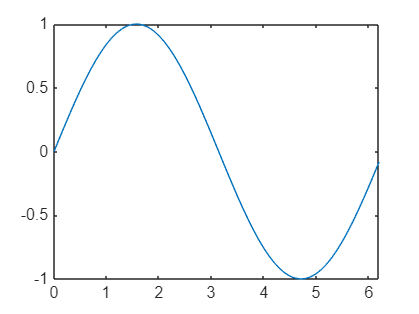

figure;
plot(x, y)

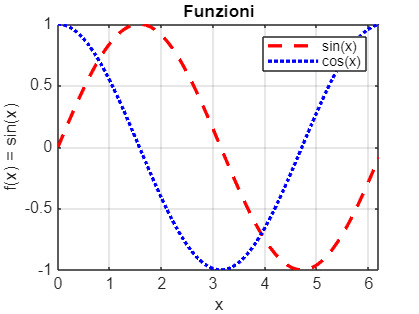

plot(x, y, 'LineWidth',2, 'Color', 'r','LineStyle', '--' )
% Possiamo modificare tante cose del nostro plot
title('Funzioni')
xlabel('x')
ylabel('f(x) = sin(x)')

grid on

hold on
plot(x, z, 'b:', 'LineWidth',2)
legend('sin(x)', 'cos(x)')